# SWING UP manouvre of a mobile pivot pendulum.

In this case study we're going to look at how to SWING UP a pendulum into a vertically upright position.  The only energy dissipation experienced by this machine, occurs as viscous friction at the pivot point "o".  The approach that we'll follow includes the following:

- Derive the angular Equation of Motion (EoM) for the machine.

- Numerically solve this EoM and visualise the PHASE-PLANE.

- Explore a swingup strategy based on negating the viscous damping of the pivot.

- Extending the above approach using an "opposite phase" control approach.

-   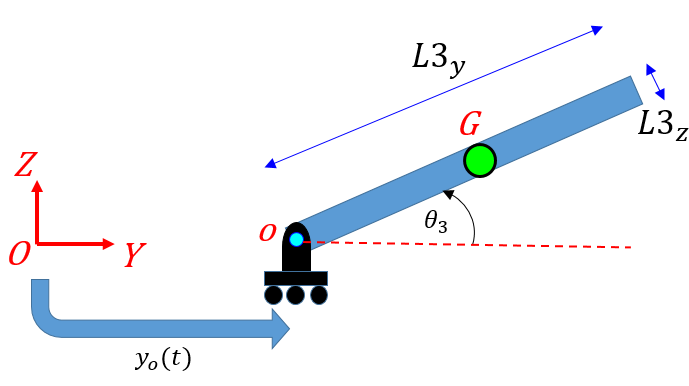     

**WHY are we doing this ?**

Our ultimate goal is to have an open chain robotic manipulator being capable of swinging up it's unactuated end link and balancing it. So in order to solve that larger problem, we'll initially focus on the simpler system that is the "mobile pivot" pendulum.

`Bradley Horton : 21-Apr-2017, bradley.horton@mathworks.com.au` 

**Define some model parameters** 

Here are some model parameters:

syms    m3_s    % masses
syms    b3_s    % damping
syms     g_s    % gravity 
syms   I_G_s    % Inertia about CoM

syms   L3X_s   L3Y_s   L3Z_s  % lengths for LINK #3

Position degrees of freedom:

syms t theta3(t)  yo(t)

Some convenience symbols:

syms theta_s  theta_D_s  theta_DD_s
syms    yo_s     yo_D_s     yo_DD_s

actual_LIST = [theta3(t), diff(theta3(t)),  diff(theta3(t),t,2), ...
                   yo(t), diff(    yo(t)),  diff(    yo(t),t,2)];
               
holder_LIST = [theta_s,  theta_D_s,  theta_DD_s, ...
                  yo_s,     yo_D_s,     yo_DD_s];

**Define Center of mass positions and TRANSLATIONAL velocities for ARM link:**

- 

**Consider LINK_3:** *What is the position vector for the center of mass "G" ? *

- 
$$y\left(t\right)=y_o \left(t\right)\text{  }+\text{ }\frac{L}{2}\ldotp \mathrm{cos}\left(\theta \right)$$


- 
$$z\left(t\right)=\frac{L}{2}\ldotp \mathrm{sin}\left(\theta \right)$$


G3      =         sym([0;0;0]);
G3(2,1) = yo(t) + (L3Y_s/2)*cos(theta3(t));  % y
G3(3,1) =         (L3Y_s/2)*sin(theta3(t));  % z

Now calculate our ***translational velocities*** and **accelerations** for the link:

WF_tran_vel_G3 = diff( G3, t); 
WF_tran_acc_G3 = diff( G3, t, 2); 

Here's what the translational velocity vector $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #3:

WF_tran_vel_G3

$$WF\_tran\_vel\_G3 = \left(\begin{array}{c} 0\\ \frac{\partial }{\partial t}\mathrm{yo}\left(t\right)-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{2}\\ \frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{2} \end{array}\right)$$

Here's what the translational acceleration vector $\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #3:

WF_tran_acc_G3

**Apply Newton's 2nd law and derive the angular equation of motion for the machine:**

y_G_DD   = WF_tran_acc_G3(2);

$$WF\_tran\_acc\_G3 = \left(\begin{array}{c} 0\\ \frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)-\frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)}^{2}}{2}-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}\\ \frac{{\mathrm{L3Y}}_{s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{2}-\frac{{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)}^{2}}{2} \end{array}\right)$$

z_G_DD   = WF_tran_acc_G3(3);
theta_DD = diff(theta3(t),t,2);

- 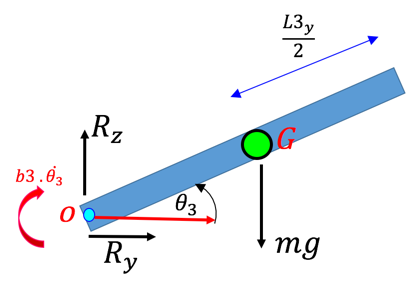

So Newton's equations are:

- 
$$m\ldotp \ddot{y_G } =\Sigma F_Y =R_Y$$


- 
$$m\ldotp \ddot{z_G } =\Sigma F_Z =R_Z -\mathrm{mg}$$


- 
$$I_G . \ddot{\theta}_G$$

$$=\Sigma M_X =R_Y \ldotp \frac{L}{2}\ldotp \sin \left(\theta \right)-R_Z \ldotp \frac{L}{2}\ldotp \cos \left(\theta \right)-b_3 \ldotp \theta^{˙}$$
 

R_Y =  m3_s * y_G_DD;
R_Z = (m3_s * z_G_DD) + m3_s*g_s;

EQ_LHS = I_G_s*theta_DD;
EQ_RHS = R_Y*(L3Y_s/2)*sin(theta3(t)) - R_Z*(L3Y_s/2)*cos(theta3(t)) - b3_s*diff(theta3(t));
EQ     = EQ_LHS == EQ_RHS;

So what does the equation of motion look like ?

EQ_theta_DD  = simplify(EQ)

Let's rearrange and isolate $\theta^{¨}$ :

new_EQ       = subs(EQ_theta_DD, diff(theta3,t,2), theta_DD_s);
THE_THETA_DD = solve(new_EQ, theta_DD_s);
expand(THE_THETA_DD)

So we can see that we have the following equation:

- 
$$\left.{\left(4\ldotp I\right.}_G +{\text{mL}}^2 \text{ }\right)\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }2\text{ }\ldotp L\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{  }-\text{ }\text{ }4\ldotp b_3 \ldotp \theta^{˙} \text{ }-\text{  }2\ldotp L\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\text{ }$$
 

Which we can rearrange to (multipy both sides by $\frac{1}{4}$):

- 
$$\left(I_G +\frac{{\text{mL}}^2 }{4}\right)\text{ }\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2}\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-{\text{  }b}_3 \ldotp \theta^{˙} \text{ }\text{ }\text{ }\text{ }-\text{ }\frac{L}{2}\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\text{ }$$


And applying the Parallel Axis Theorem:  $I_{o\text{ }} =I_{G\text{  }} +{\mathrm{md}}^2 \text{ }=I_G \text{ }+\frac{{\text{mL}}^2 }{4}\text{ }$

- 
$$I_o \text{ }\ldotp \theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2}\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\text{ }{\text{ }b}_3 \ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2}\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\mathit{ }$$


or isolating $\theta^{¨}$ we get :

- 
$$\theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2\ldotp I_o }\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\frac{b_3 }{I_o }\ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2\ldotp I_o }\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\mathit{ }$$


**What does the numeric solution look like ?**

Convert into a system of 1st order ODEs with the following state vector:

- $q=\left\lbrace \theta ,\dot{\text{ }\theta } \right\rbrace$  and  $\dot{q} =\left\lbrace \theta^{˙} ,\ddot{\text{  }\theta } \right\rbrace$

q0                   = [0,0]';
q_dot_col_s(1,1)     = formula( diff(theta3(t),t)  );
q_dot_col_s(2,1)     = formula(  THE_THETA_DD  );

$$EQ\_theta\_DD = m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)+4\,I_{G,s}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)+4\,b_{3,s}\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)+g_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)\,{\mathrm{L3Y}}_{s}\,2=2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)$$

 Do a variable substitution:

q_dot_col_s = subs(q_dot_col_s, actual_LIST, holder_LIST)

Let's consider the case where the ***pivot point of the pendulum is fixed*** (ie: $0=y_o \left(t\right)=\dot{y_o } =\ddot{y_o }$) . 

new_q_dot_col_s = q_dot_col_s;
new_q_dot_col_s = subs(q_dot_col_s, yo_DD_s, 0)

$$ans = \frac{2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{yo}\left(t\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{4\,b_{3,s}\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}-\frac{2\,{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}}$$

Define a set of initial conditions:

- $q=\left\lbrace \theta ,\dot{\text{ }\theta } \right\rbrace$  and  $\dot{q} =\left\lbrace \theta^{˙} ,\ddot{\text{  }\theta } \right\rbrace$

q0                   = [0,0]';

And numerically solve the system:

bh_pend_solve_ODE_sys(new_q_dot_col_s, q0)

When we look at the PHASE-PLANE plot, we see (as expected) that the pendulum oscillates AND loses energy along the way ... until it comes to a stop at the vertically DOWN position.

**A SWINGUP strategy  - a 1st attempt**

- 

Now let's look at a situation where we are moving the pivot point.  First recall our original system equation:

- 
$$\theta^{¨} \text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\frac{L}{2\ldotp I_o }\ldotp m\ldotp \sin \left(\theta \right)\ldotp \ddot{y_O } \text{   }-\frac{b_3 }{I_o }\ldotp \theta^{˙} \text{   }-\text{  }\frac{L}{2\ldotp I_o }\ldotp g\ldotp m\ldotp \cos \left(\theta \right)\mathit{ }$$


So what would happen if we chose:

- 
$$\ddot{y_o } \left(t\right)=k\ldotp \frac{{2\ldotp I}_o }{L\ldotp m\ldotp \sin \left(\theta \right)}\text{ }\ldotp \frac{b_3 }{I_o }\ldotp \theta^{˙} \text{ }\text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\text{ }\text{ }\text{ }k\ldotp \frac{{2\text{ }\ldotp \text{ }b}_3 \text{ }\ldotp \theta^{˙} \text{ }}{L\ldotp m\ldotp \sin \left(\theta \right)}$$


It looks like we could "pump" energy into the system faster than it's being dissipated by the viscous damping - NOTE when implemented we'd need to treat the singularities at $0=\mathrm{sin}\left(\theta \right)$in a sensible way. So let's define the following state vector and initial conditions and see what happens:

- $q=\left\lbrace \theta ,\dot{\text{ }\theta } ,{\text{ }\text{ }\text{ }y}_o \text{ },\dot{y_o } \right\rbrace$  and  $\dot{q} =\left\lbrace \theta^{˙} ,\ddot{\text{  }\theta } ,\text{    }\dot{\text{ }y_o } \text{ },\ddot{\text{  }y_o } \right\rbrace$  

- $q_0 =\left\lbrace \frac{-1\ldotp \pi }{180},0,0,0\right\rbrace$ , *ie: the pendulum is almost horizontal, *$\theta ={-1}^o$

First consider the case when *k=1* .  In this situation we're adding energy into the system at the same rate that the damping is removing it. So? - So we'd expect to see a system response similar to an UNdamped system, ie: no energy dissipation:

k                        = 1;
q0                       = [-1*pi/180,0,0,0]';
thetaD_and_thetaDD_col_s = q_dot_col_s;

$$q\_dot\_col\_s = \left(\begin{array}{c} \theta_{D,s}\\ -\frac{4\,b_{3,s}\,\theta_{D,s}+2\,{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\cos\left(\theta_{s}\right)-2\,{\mathrm{L3Y}}_{s}\,m_{3,s}\,{\mathrm{yo}}_{\mathrm{DD},s}\,\sin\left(\theta_{s}\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}} \end{array}\right)$$

bh_pend_solve_ODE_sys_custom( thetaD_and_thetaDD_col_s, q0, k );

Next consider the case when *k=1.04* .  In this situation we're adding energy into the system faster than the damping can remove it. So? - So we'd expect to see a system response similar to an UNSTABLE system:

k                        = 1.04;

$$new\_q\_dot\_col\_s = \left(\begin{array}{c} \theta_{D,s}\\ -\frac{4\,b_{3,s}\,\theta_{D,s}+2\,{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\cos\left(\theta_{s}\right)}{m_{3,s}\,{{\mathrm{L3Y}}_{s}}^{2}+4\,I_{G,s}} \end{array}\right)$$

q0                       = [-1*pi/180,0,0,0]';
thetaD_and_thetaDD_col_s = q_dot_col_s;
[t_col, q_mat, ydd_col]  = bh_pend_solve_ODE_sys_custom( thetaD_and_thetaDD_col_s, q0, k );
    

For this scenario, note the time trace for $y_o \left(t\right)\text{ }$shown below.  **NOTE** how far the pivot point is being moved.

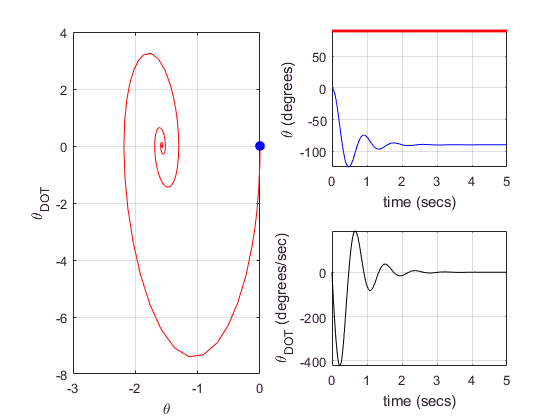

figure;

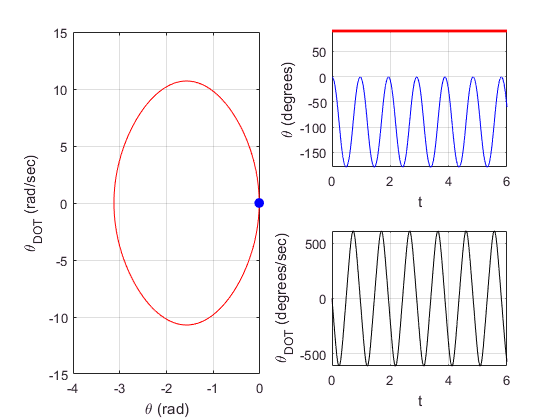

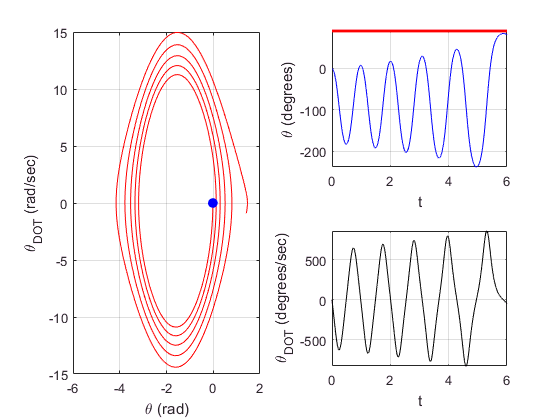

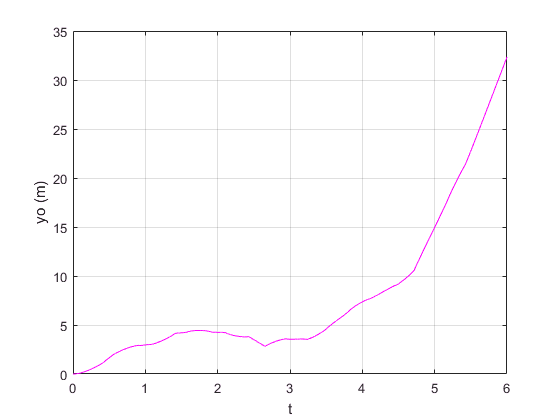

plot(t_col, q_mat(:,3), '-m'); grid('on'); xlabel('t'); ylabel('yo (m)');

So although a "swing UP" strategy of the form:

- 
$$\ddot{y_o } \left(t\right)=k\ldotp \frac{{2\ldotp I}_o }{L\ldotp m\ldotp \sin \left(\theta \right)}\text{ }\ldotp \frac{b_3 }{I_o }\ldotp \theta^{˙} \text{ }\text{ }\text{ }\text{ }\text{ }=\text{ }\text{ }\text{ }\text{ }\text{ }k\ldotp \frac{{2\text{ }\ldotp \text{ }b}_3 \text{ }\ldotp \theta^{˙} \text{ }}{L\ldotp m\ldotp \sin \left(\theta \right)}$$


does indeed swingup the pendulum.  It unfortunately requires a large translational range for $y_o \left(t\right)$.

**A SWINGUP strategy  - a 2nd attempt**

- 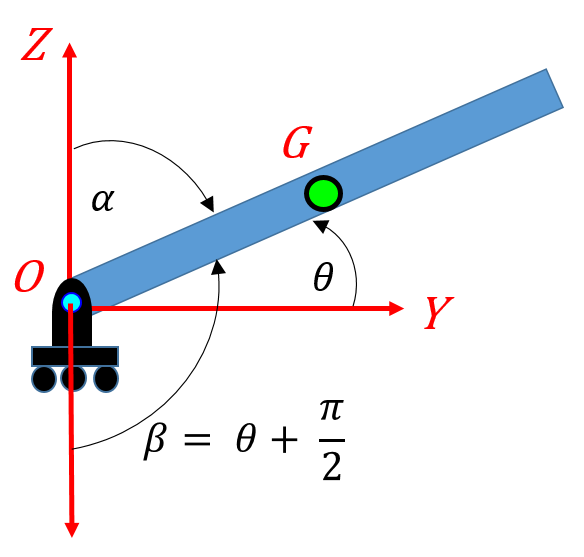

In the previous example we focused on creating a motion profile for the pivot point based on the acceleration of the pivot point, ie: $\ddot{y_o }$. And (not unexpectedly) this did NOT allow us to constrain the range of travel experienced by the pivot point.  So as a 2nd attenpt, let's focus on specifying directly the motion profile of $y_o \left(t\right)$.  The approach that we'll take is based on the following:

- assume that the pendulum is initially in the hanging down equilibrium position

- for a short period, oscillate the pivot at the pendulum's natural frequency

- then switch to an oscillation that is 180 degrees out of phase with the pendulum's PHASE-PLANE angle

**Simulink model implementation:**

The Simulink model <`bh_proto_swingup_OUT_OF_PHASE_CONTROL.slx`> shows the implementation of this approach.  NOTE the following:

- The algorithm has been implemented into a MATLAB function block which hs a sample time of:  $\Delta t=0\ldotp 001\text{ }\mathrm{seconds}$

- We specify that the pivot motion range is bounded by:  $-0\ldotp 1\le y_{o\text{ }} \left(t\right)\le 0\ldotp 1$

- We have a "tuning" parameter k, which allows us to adjust the excitation frequency.

- We apply a gentle 2nd order low pass filter to the algorithm output

When you run the Simulink model, you get the following system response:

-